# Multivariable Linear Least Regression Method

*MohammadSina GhanbariPakdehi, Chemical and Petroleum Engineering Department, Fall 2021*

Multivariable Linear Regression is a statistical technique used to model and analyze the relationship between multiple independent variables and a single dependent variable. It extends the principles of simple linear regression to scenarios where more than one predictor variable influences the outcome. This method seeks to identify a linear equation that best fits the data by minimizing the squared differences between predicted and actual values. By considering multiple predictors, multivariable linear regression enables the exploration of complex relationships and provides insights into how different factors collectively contribute to the variability observed in the dependent variable. This powerful tool finds applications across various fields, from economics and social sciences to engineering and machine learning, offering a means to quantify and understand intricate patterns within data sets with multiple influencing factors. Assume that *y *variable is dependent to many *x* variables, and its dependency is shown in the table below:

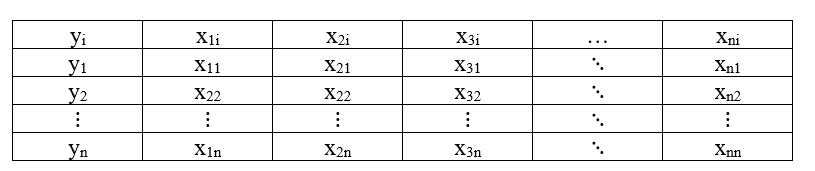

The goal of linear regression is to find a linear equation of the form $y=a_0 +a_1 \ldotp x_1 +a_2 \ldotp x_2 +\ldotp \ldotp \ldotp +a_n \ldotp x_n$, where $a_1$ represents the slope of line, and $a_0$ represents the y-intercept. 

### Part1: Input data

% Multivariable Linear regression
clear, clc

x = [2.5,1.8,3.2;3,2,2.8;2.8,1.5,3;2.2,1.7,2.5;2.6,1.9,2.7;3.2,2.2,2.9;2.9,1.6,3.1;2.7,1.8,2.4;3.5,2.3,3.5;3.1,2.1,3.3];
y = [5.7,6.2,5.9,5,5.4,6.8,6.1,5.5,7,6.5]';
n = size(x, 2); % Number of features (columns)

### Part2: Calculation process

In this part, a system of linear equations for finding the coefficients should be created. Its general form is:


$$\left\lbrack \begin{array}{ccccc}
n & \sum_i \;x_{1i}  & \sum_i \;x_{2i}  & \cdots  & \sum_i \;x_{\mathrm{ni}} \\
\sum_i \;x_{1i}  & \sum_i \;x_{1i}^2  & \sum_i \;x_{1i} x_{2i}  & \cdots  & \sum_i \;x_{1i} x_{\mathrm{ni}} \\
\vdots  & \vdots  & \ddots  & \ddots  & \vdots \\
\sum_i \;x_{\mathrm{ni}}  & \sum_i \;x_{\mathrm{ni}} x_{1i}  & \sum_i \;x_{\mathrm{ni}} x_{2i}  & \cdots  & \sum_i \;x_{\mathrm{ni}}^2 
\end{array}\right\rbrack \times \left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
\vdots \\
a_n 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\sum_i \;y_i \\
\sum_i \;x_{1i} y_i \\
\vdots \\
\sum_i \;x_{\mathrm{ni}} y_i 
\end{array}\right\rbrack$$


Coeff = zeros(n + 1, n + 1); % Coefficient matrix

% Fill the first row and column of Coeff
Coeff(1, 1) = length(y);
Coeff(2:end, 1) = sum(x)';
Coeff(1, 2:end) = sum(x);

% Fill the remaining cells of Coeff
for i = 2:n+1
    for j = 2:n+1
        Coeff(i, j) = x(:, i-1)' * x(:, j-1);
    end
end

Ans = ones(n + 1, 1); % Answer vector
Ans(1) = sum(y);
Ans(2:end) = x' * y;

Final = Coeff \ Ans;
disp(['a0';'a1';'a2';'a3']), disp('='), disp(Final)

a0
a1
a2
a3
=
    0.7973
    1.3293
    0.1999
    0.3560



### Part3: Visualization

Visualization is one of the fast methods to see how much the linearization is accurate. Note that visualization just shows the quality of accuracy not its value! 

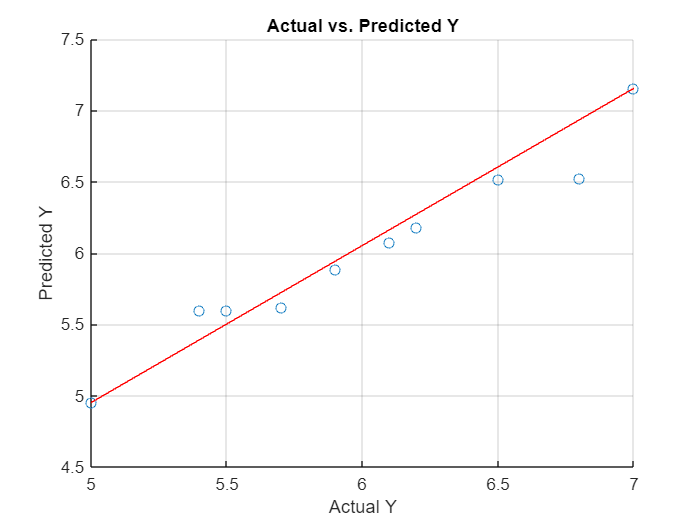

y_new = ones(length(y),1);
for i = 1:length(y)
    y_new(i) = Final(1) + Final(2)*x(i,1) + Final(3)*x(i,2) + Final(4)*x(i,3);
end

scatter(y, y_new);
hold on
plot([min(y), max(y)], [min(y_new), max(y_new)], 'r'); % Plotting regression line
xlabel('Actual Y');
ylabel('Predicted Y');
title('Actual vs. Predicted Y');
grid on;

### Part4: Measurement of the linearization accuracy

Using Coefficient of determination ($r^2$), the accuracy of linearization can be measured easily. First, the Residual sum of squares should be calculated using the formula below:


$$S_r =\sum_{i=1}^n {\left(y_i -a_0 -a_1 x_i \right)}^2$$


Then, First, the mean deviation squares should be calculated by the following equation:


$$S_t =\sum_{i=1}^n {\left(y_i -\bar{y} \right)}^2$$



$$r^2 =\frac{\left(S_t -S_r \right)}{S_t }$$


Sr = sum((y - y_new).*(y - y_new));
St = sum((y- mean(y)).*(y- mean(y)));
r2 = (St - Sr)/St;
disp('The Coefficient of determination is: '), disp(r2)

The Coefficient of determination is: 
    0.9565

